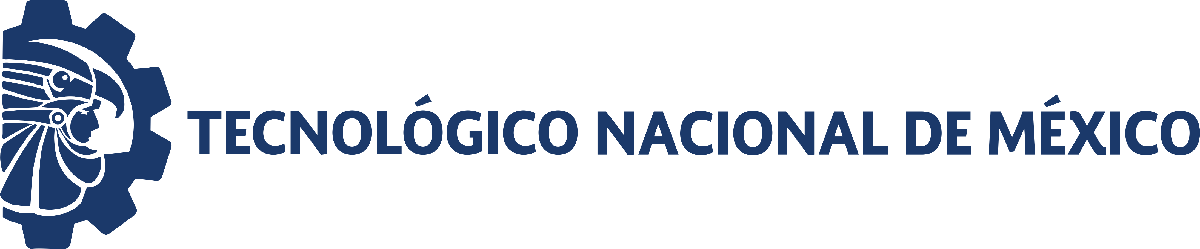                                 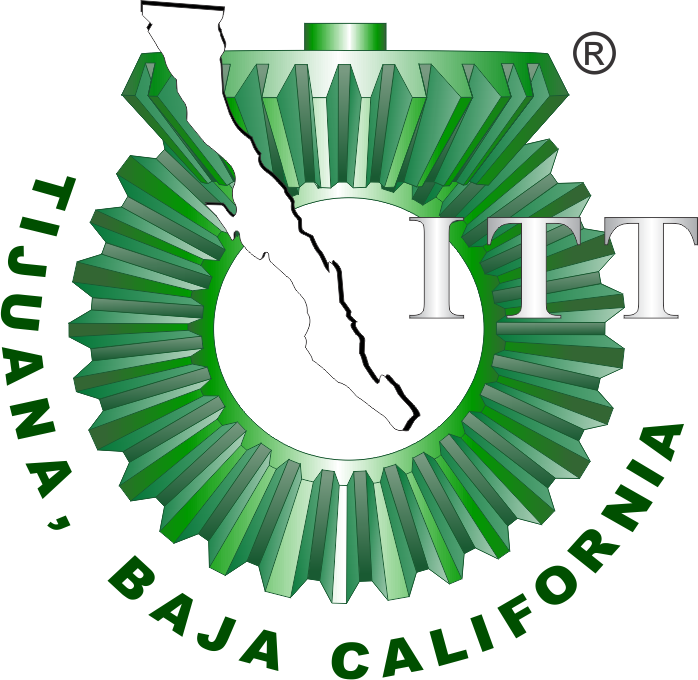

# Práctica uno: Diseño de controlador para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

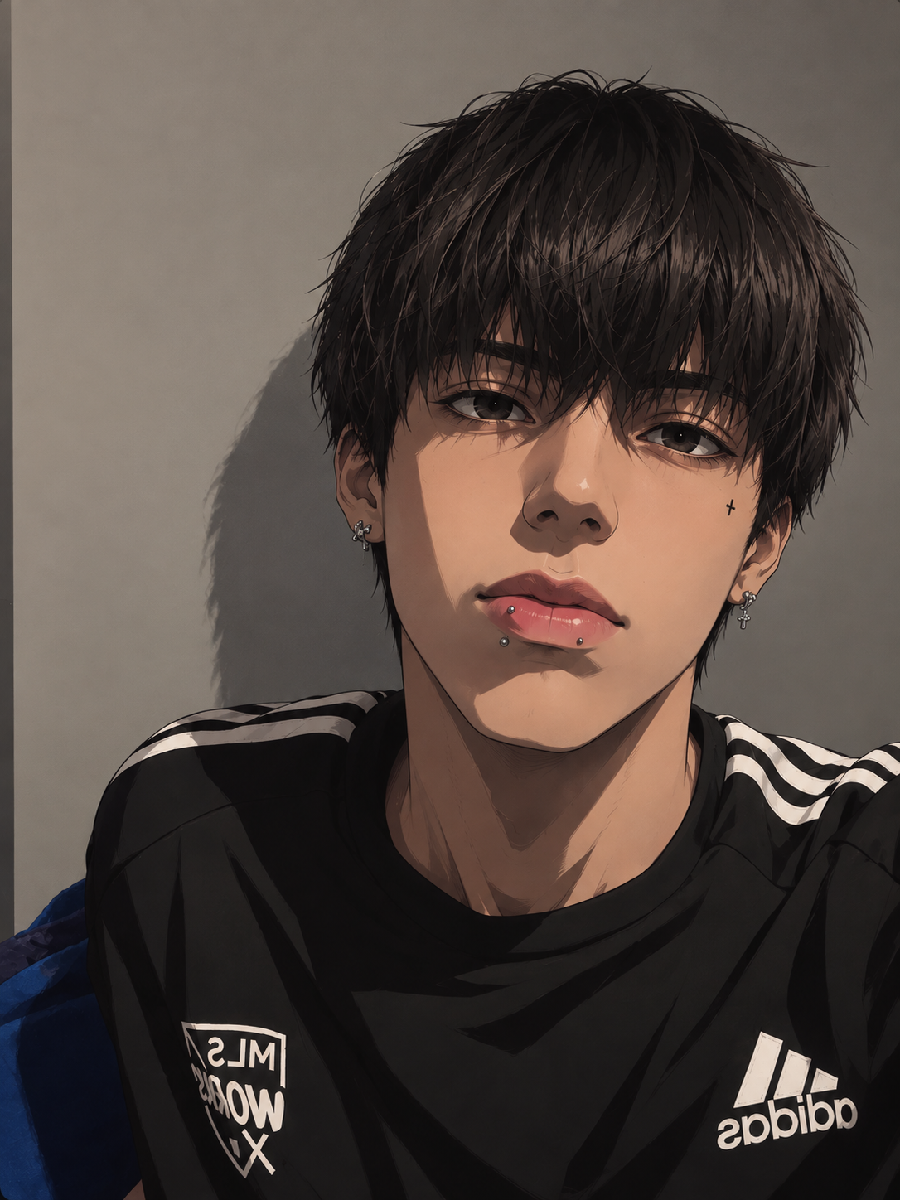

Nombre del alumno: Armenta Medina Osmar Ediel

Número de control: 23212178

Correo institucional: l23212178**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
% set_param('sistema/PpL(t): CE/PpL','VectorFormat','1D-array');
x = sim('sistema',parameters);

% writematrix(Pa,'C:\Users\ediel\OneDrive\Escritorio\modelado\Unidad 3\signal.xlsx');

## Respuesta al impulso unitario

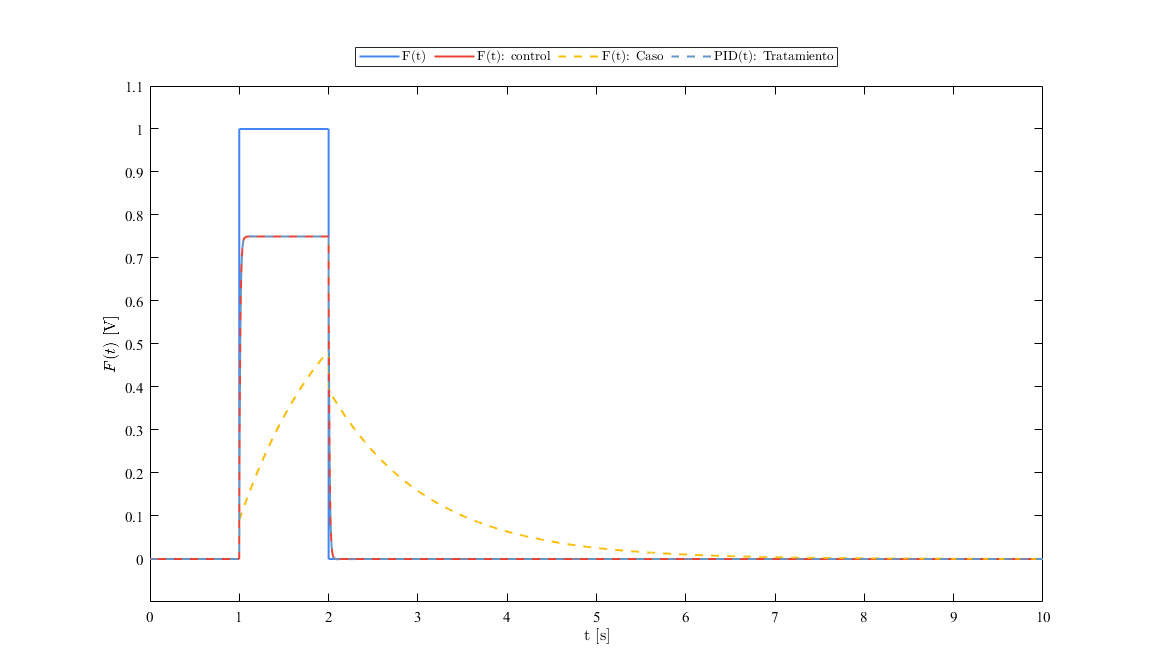

x = sim('sistema',parameters);
plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID, 'impulso unitario')  

## Funcion: Respuestas de la simulacion 

function plotsignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [0.5,0.5,12,7])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [66, 133, 244]/255;  
    clr2 = [234, 67, 53]/255;   
    clr3 = [251, 188, 5]/255;   
    clr4 = [100,150,200]/255;
    order = [clr1; clr2; clr3;clr4]; colororder(order)


    xlabel('t [s]','Interpreter','latex')
    ylabel('$F(t)$ [V]', 'Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(0:0.1:1.1)

    if signal == "impulso unitario"

        plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('F(t)','F(t): control','F(t): Caso','PID(t): Tratamiento');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
        
     

    end
    set(gcf,'Color','white')
    set(gca,'Color','white','XColor','black','YColor','black')
    set(L,'Color','white','TextColor','black')

    
end